# **JacobiSD**

[Jacobi elliptic function sd](https://dlmf.nist.gov/22)

## Definition


$$\mathrm{sd}\left(x\left|m\right.\right)\equiv \frac{\mathrm{sn}\left(x\left|m\right.\right)}{\mathrm{dn}\left(x\left|m\right.\right)}$$



$$\mathrm{sd}\left(x,k\right)\equiv \mathrm{sd}\left(x\left|k^2 \right.\right)$$


where *m *is the parameter, *k *is the modulus, and dn and sn are Jacobi elliptic functions function.

Domain: $-\infty <x<\infty$, $-\infty <m<\infty$. For the specified domain, the  codomain of *sd *is the set of real numbers.

Basic features:

$\mathrm{sd}\left(x+4K\left(m\right)\left|m\right.\right)=\mathrm{sd}\left(x\left|m\right.\right)$  (periodic) ,  $\mathrm{sd}\left(-x\left|m\right.\right)=-\mathrm{sd}\left(x\left|m\right.\right)$ (odd)

Special values:


$$\mathrm{sd}\left(0\left|m\right.\right)=0$$


$\mathrm{sd}\left(x\left|0\right.\right)=\mathrm{sin}\;x$,  $\mathrm{sd}\left(x\left|1\right.\right)=\mathrm{sinh}\;x$

Identities:


$$\mathrm{sd}\left(x\left|m\right.\right)=\mathrm{sc}\left(x\sqrt{m}\left|m^{-1} \right.\right)/\sqrt{m}$$


## Syntax

Y = JacobiSD(X,K)

y = jsd(x,k)

Y = mJacobiSD(X,M)

y = mjsd(x,m)

## Description

Y = JacobiSD(X,K) returns the Jacobi elliptic function $\mathrm{ds}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **JacobiSD** is the wrapper function which calls the functions **jsd** element-wise via the function **ufun2**.

y = jsd(x,k) returns the Jacobi elliptic function $\mathrm{ds}\left(x,k\right)$ for argument x and the modulus k. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed. **jsd** calls the functions **sncndn **for calculation of$\mathrm{ds}\left(x,k\right)$ .

Y = mJacobiSD(X,M) returns the Jacobi elliptic function $\mathrm{ds}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mJacobiSD** is the wrapper function which calls the function **mjsd** element-wise via the function **ufun2**.

y = mjsd(x,m) returns the Jacobi elliptic function $\mathrm{ds}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed.  **mjsd** calls the functions **sncndn **for calculation of $\mathrm{ds}\left(x\left|m\right.\right)$ .

**sncndn **implements the AGM transformation for simultaneously  computation of the functions *sn*, *cn*, *dn* . For $m>1$ the Jacobi's transformation is used [1,2].

## Precision

## **Numerical Examples**

**Salar input**

format long
k = 0.5; 
x = 0.5;
[jsd(x,k), JacobiSD(x,k), mjsd(x,k^2), mJacobiSD(x,k^2)]

ans =    0.489081727242946   0.489081727242946   0.489081727242946   0.489081727242946


Accuracy

fprintf('%.16g\n',jsd(3,5))

-0.2346384259274694


% Maple -0.2346384259274686_26

[MATLAB example](https://www.mathworks.com/help/symbolic/jacobisd.html)

disp(mJacobiSD([2 1 -3],[1 2 3]))

   1.0e+02 *

   0.036268604078470   0.021629219942742  -1.263078219313229



fprintf('%.16g\n',mjsd(3,5))

0.03122057986453885


% MATLAB 0.03122057986453878_5956650143970485


Identities

x=2;
m = 0.12; % m > 0
disp(mjsd(x,m)-1/sqrt(m)*mjsc(x*sqrt(m),1/m))

     2.220446049250313e-16



**Vector input**

X=[1 2 3 4];
disp(JacobiSD(X,0)-sin(X))

     0     0     0     0



m = 0.12; 
disp(mJacobiSD(X,m)-mJacobiSC(X*sqrt(m),1/m)/sqrt(m))

   1.0e-15 *

   0.222044604925031   0.222044604925031   0.444089209850063  -0.111022302462516



**Matrix input**

X=[1 2; 3 4];
disp(JacobiSD(X,1)-sinh(X))

   1.0e-14 *

   0.022204460492503  -0.044408920985006
                   0   0.355271367880050



M = [1 2; 0.2 0.3]; 
disp(mJacobiSD(X,M)-mJacobiSC(X.*sqrt(M),1./M)./sqrt(M))

     0     0
     0     0



## **Graphs **

**Example 1**

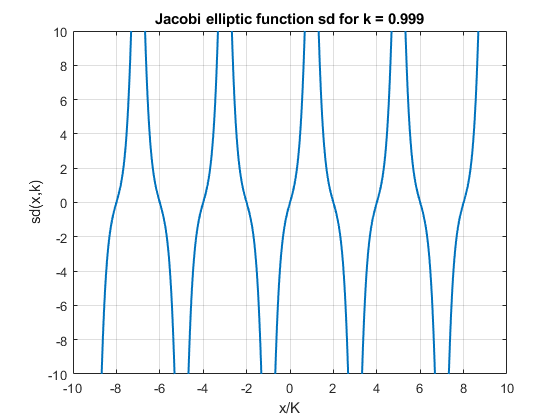

figure
x=-9:0.01:9;
k = 0.999;
K = elK(k);
plot(x,JacobiSD(x*K,k),'LineWidth',1.5)
xlabel('x/K')
ylabel('sd(x,k)')
ylim([-10 10])
title(sprintf('Jacobi elliptic function sd for k = %g',k))
grid on

**Example 2**

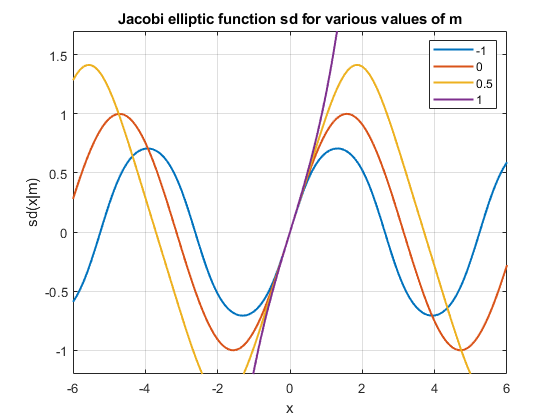

figure
X = -6:0.1:6;
M = [-1,0,0.5,1];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mJacobiSD(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -1.2 1.7])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Jacobi elliptic function sd for various values of m')
xlabel('x')
ylabel('sd(x|m)')

**Example 3**

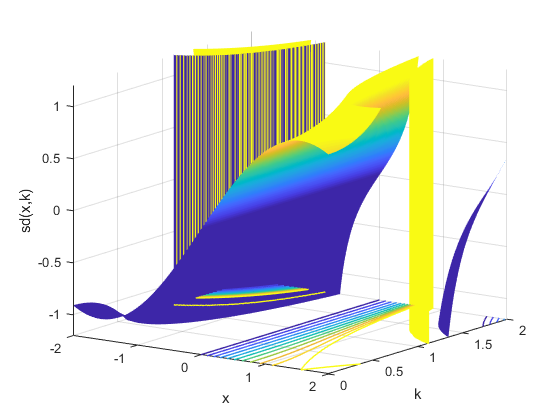

figure
x=-2:0.01:2;
k=0:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,JacobiSD(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -1.2;
hc.LineWidth = 1;
hc.LevelList = 0:0.1:1;
caxis([0 1])
view([35 15]);
xlabel('x')
ylabel('k')
zlabel('sd(x,k)')
zlim([-1.2 1.2])
grid on

**Example 4**

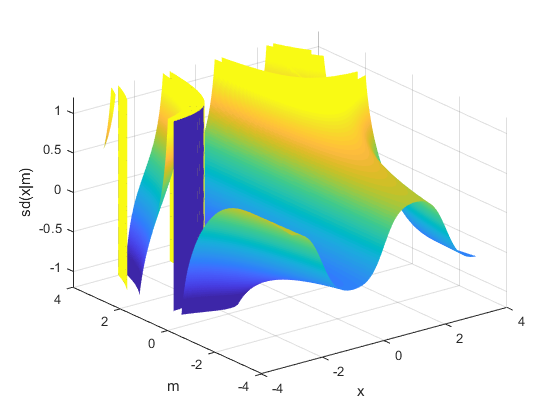

figure
x=-3:0.01:3;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
surface(X,M,mJacobiSD(X,M),'EdgeColor','none')
view(3)
caxis([-1 1])
xlabel('x')
ylabel('m')
zlabel('sd(x|m)')
zlim([-1.2 1.2])
grid on

**Example 5**

[MATLAB example](https://www.mathworks.com/help/symbolic/jacobisd.html)

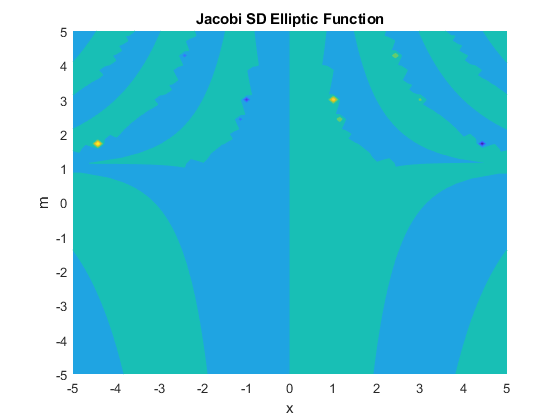

figure
f = @(x,m)mJacobiSD(x,m);
fcontour(f,'Fill','on') %,'LevelList',-3:0.1:3,'MeshDensity',200)
title('Jacobi SD Elliptic Function')
xlabel('x')
ylabel('m')

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions. Numerische Mathematik 7, 78-90, 1965

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also